rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data
load breast.mat


length(labels_train==1)

ans = 400

length(labels_test==1)

ans = 169

sum(labels_train==1)/length(labels_train==1)

ans = 0.3750

sum(labels_test==1)/length(labels_test==1)

ans = 0.3669

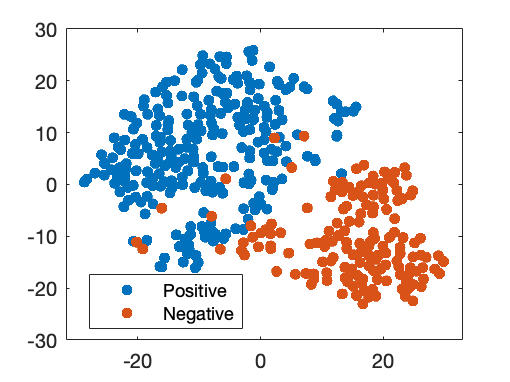

figure;
out = tsne(zscore(trainset),'Algorithm','exact','Distance','Euclidean');
gscatter(out(:,1),out(:,2),labels_train)
legend('Positive','Negative')

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_1411_3.png','Resolution',300)

run=[1:100];

simplex=[];
for r=run,
    [gam , sig2, cost] = tunelssvm({ trainset , labels_train , 'c', [], [], 'lin_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex=[simplex; gam, sig2, cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.080418
                                          F(X)=         0.035
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 lin_kernel
 

 3. starting value:                   0.080418

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     3.500000e-02     -2.5205           initial 
     2           5     3.500000e-02     -2.5205           shrink 
     3           7     3.500000e-02     -2.5205           contract outside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=0.080418  , F(X)=3.500000e-02 

Obtained hyper-parameters: [gamma]: 0.080418

   Determine initial 

tend = toc;


fprintf('\n LINEAR: median gamma = %.2f  ', median(simplex(:,1)))
fprintf('\n LINEAR: median cost = %.2f  ', median(simplex(:,2)))

run=[1:100];
simplex_rbf=[];
for r=run,
    [gam ,sig2 , cost] = tunelssvm({ trainset , labels_train , 'c', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex_rbf=[simplex_rbf; gam ,sig2 , cost];
end
tend = toc;

fprintf('\n RBF: median gamma = %.2f  ', median(simplex_rbf(:,1)))
fprintf('\n RBF: median sig = %.2f  ', median(simplex_rbf(:,2)))
fprintf('\n RBF: median cost = %.2f  ', median(simplex_rbf(:,3)))

run=[1:100];
simplex_poly=[];
for r=run,
    [gam, t, cost] = tunelssvm({ trainset , labels_train , 'c', [], [], 'poly_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex_poly=[simplex_poly; gam ,t(:,1), t(:,2) , cost];
end
tend = toc;

fprintf('\n Poly: median gamma = %.2f  ', median(simplex_poly(:,1)))
fprintf('\n Poly: median t = %.2f  ', median(simplex_poly(:,2)))
fprintf('\n Poly: median degree = %.2f  ', median(simplex_poly(:,3)))
fprintf('\n Poly: median cost = %.2f  ', median(simplex_poly(:,4)))

gam = 4.47;
sig2 = 37.5;

% Train the classification model.
[ alpha , b ] = trainlssvm ({ trainset , labels_train , 'c', gam , sig2 ,'RBF_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ trainset , labels_train , 'c', gam , sig2 ,'RBF_kernel'} , { alpha , b } , testset ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , labels_test ) 


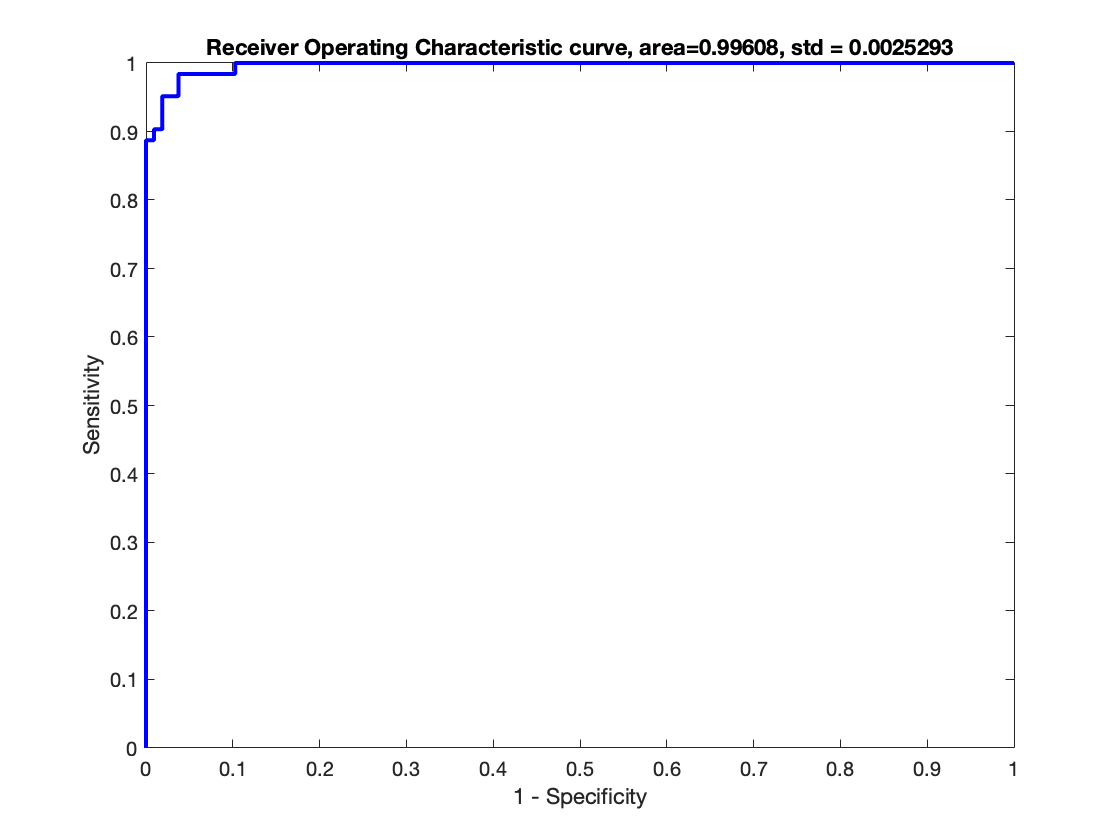

gam = 0.14;

% Train the classification model.
[ alpha , b ] = trainlssvm ({ trainset , labels_train , 'c', gam  ,[], 'lin_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ trainset , labels_train , 'c', gam  ,[],'lin_kernel'} , { alpha , b } , testset ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , labels_test) 

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_141_3.png','Resolution',300)